Voreinstellungen

prec=1/100;
range=10;

Symbole

syms t n tau;

Wertebereiche

T=-range:prec:range;
N=-range:range;

zeitkontinuierlich,wertkontinuierlich

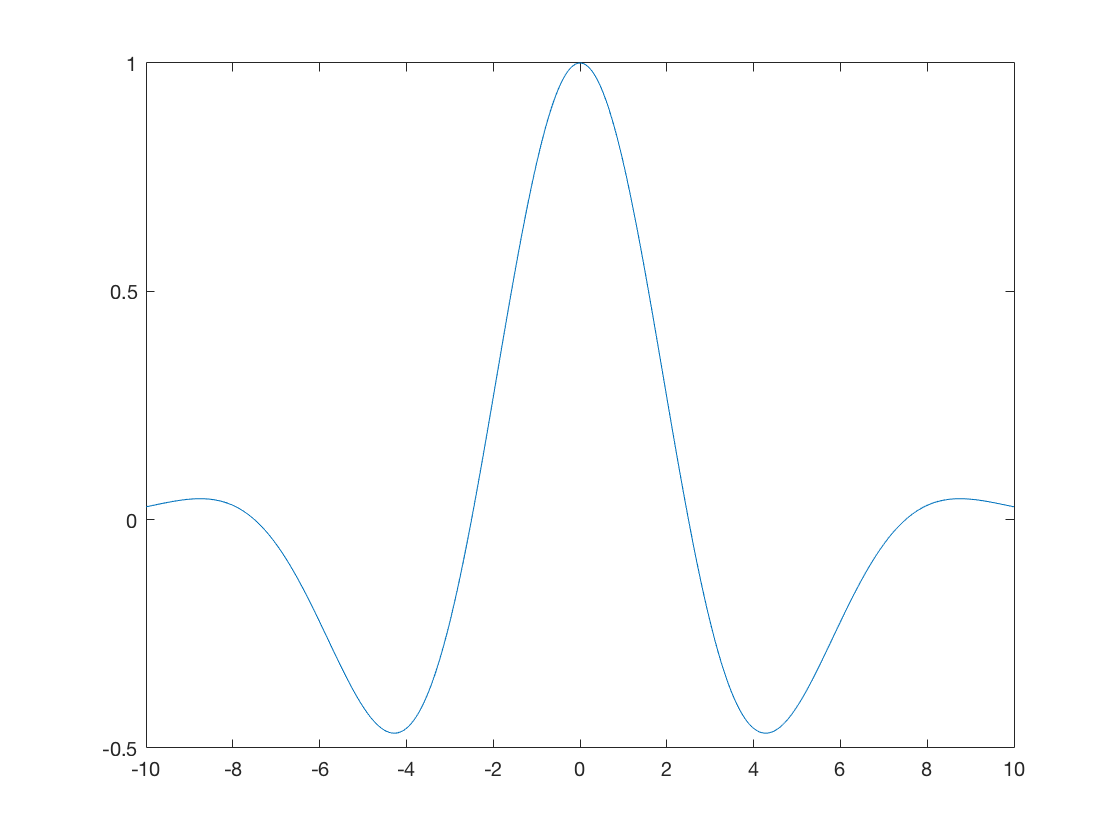

XT=gauspuls(T,1/10,1);
plot(T,XT)

zeitkontinuierlich,wertdiskret

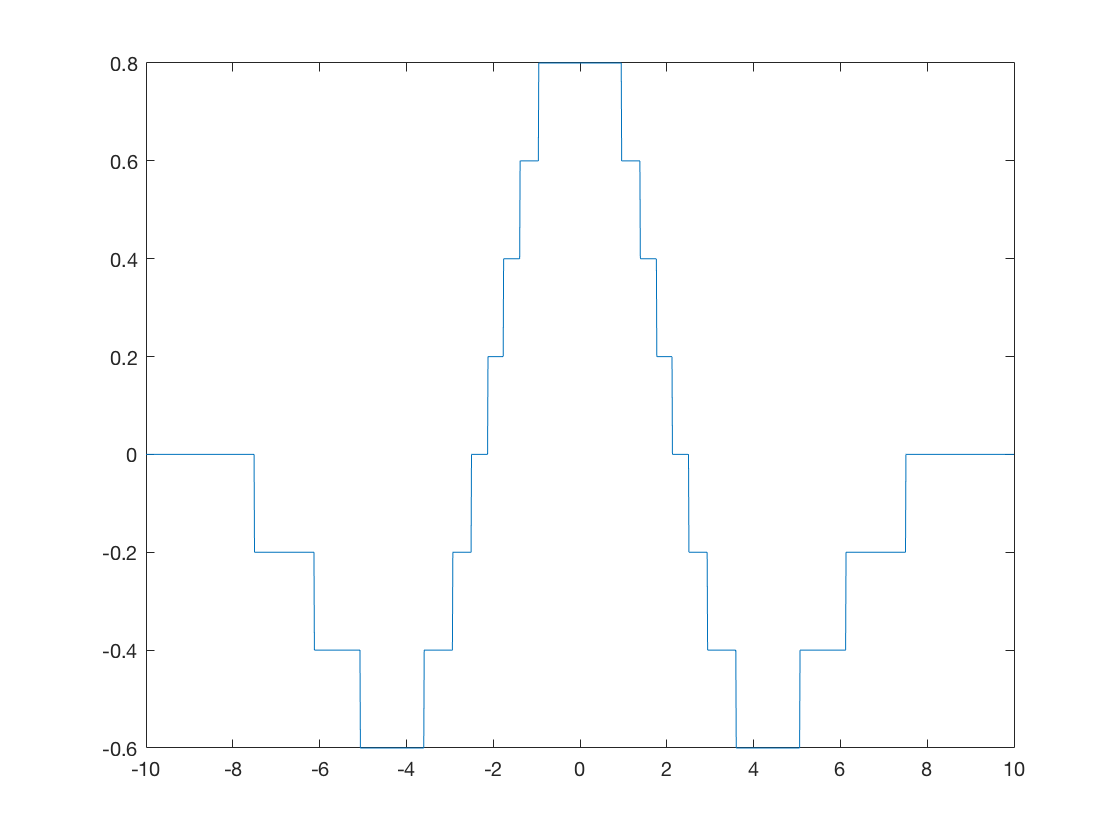

[indexT,QT]=quantiz(XT,[-1:.2:1],[-1.2:.2:1]);
plot(T,QT)

zeitdiskret,wertkontinuierlich

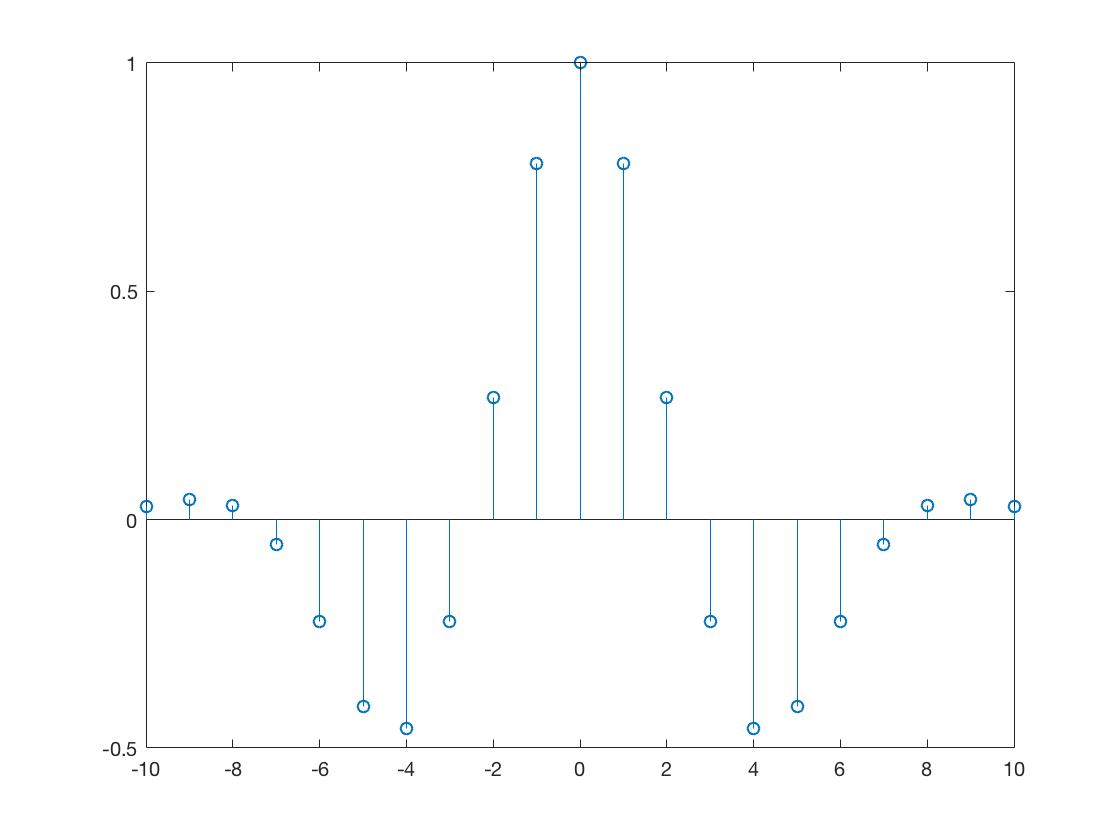

XN=gauspuls(N,1/10,1);
stem(N,XN)

zeitdiskret,wertdiskret

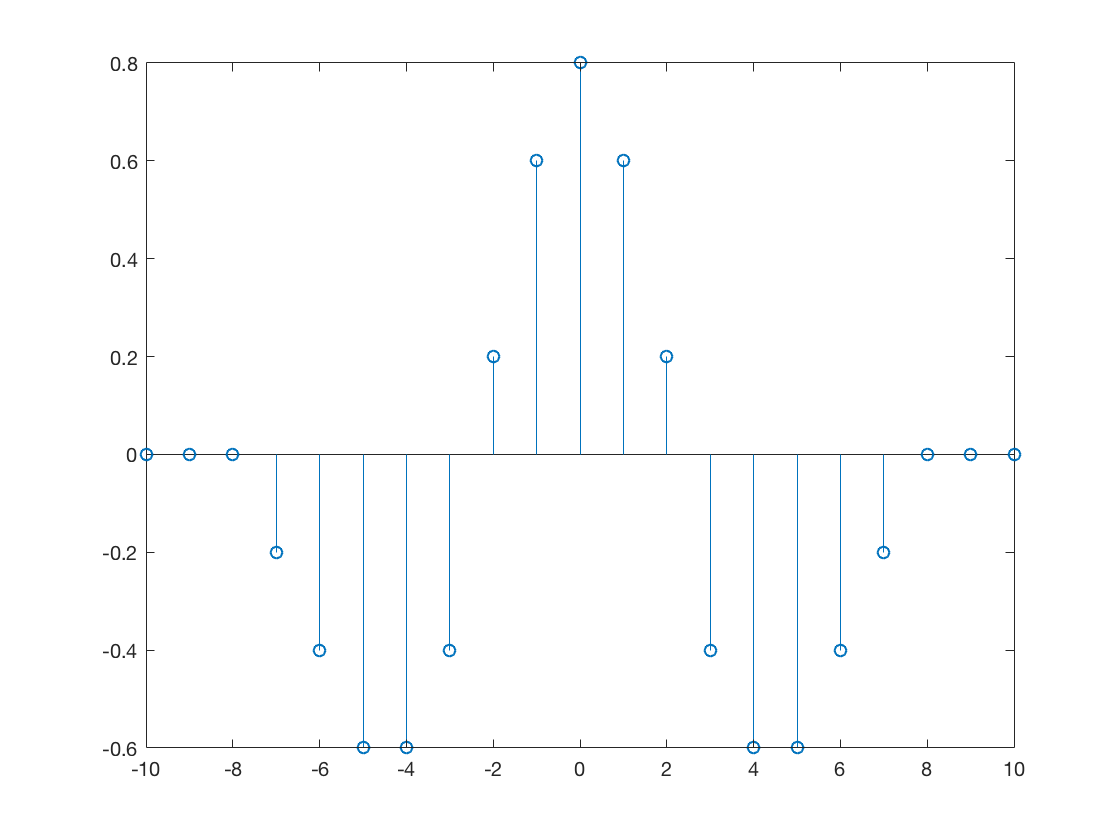

[indexN,QN]=quantiz(XN,[-1:.2:1],[-1.2:.2:1]);
stem(N,QN)

Einheitsimpuls,zeitdiskret

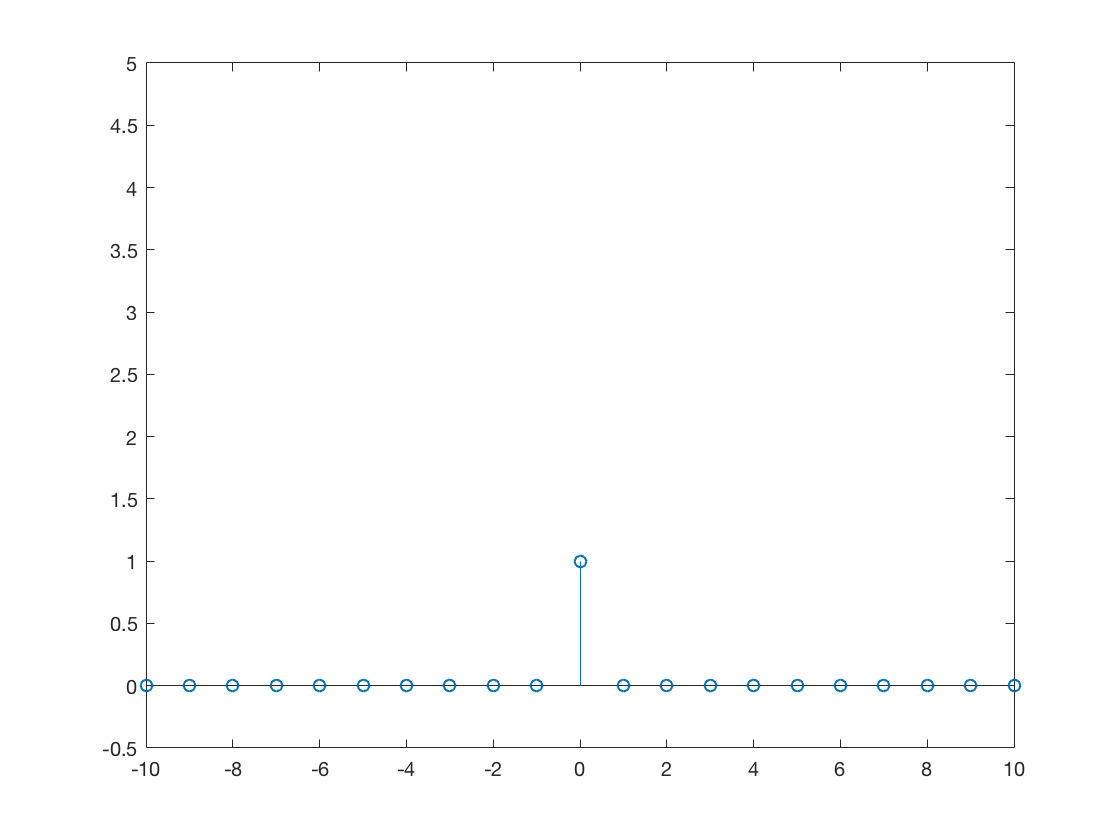

DN=zeros(1,2*range+1);
DN(N==0)=1;
DN(range+1)=1;
stem(N,DN)
axis([-range range -1/2 range/2])

Einheitssprung,zeitkontinuierlich

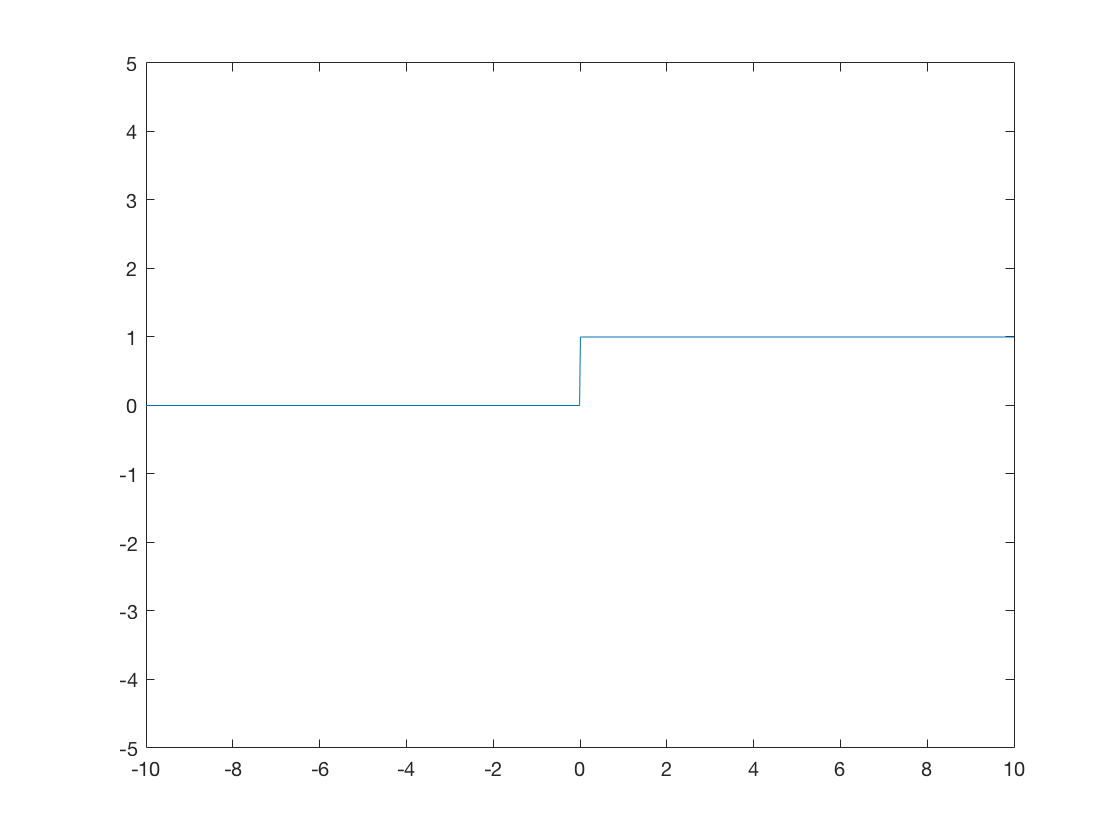

UT=heaviside(T);
plot(T,UT)
axis([-range range -range/2 range/2])

Einheitsprung,zeitdiskret

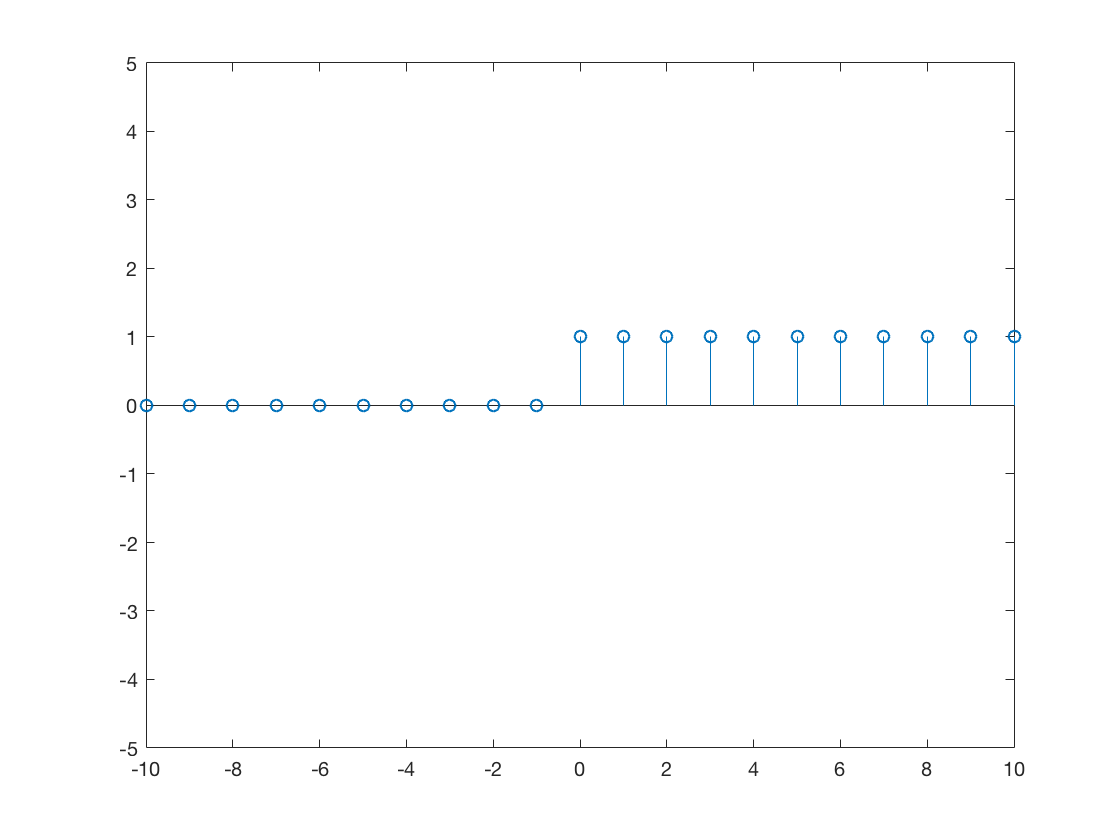

UN=heaviside(N);
UN(range+1)=1;
stem(N,UN)
axis([-range range -range/2 range/2])

Dirac-Delta-Funktion

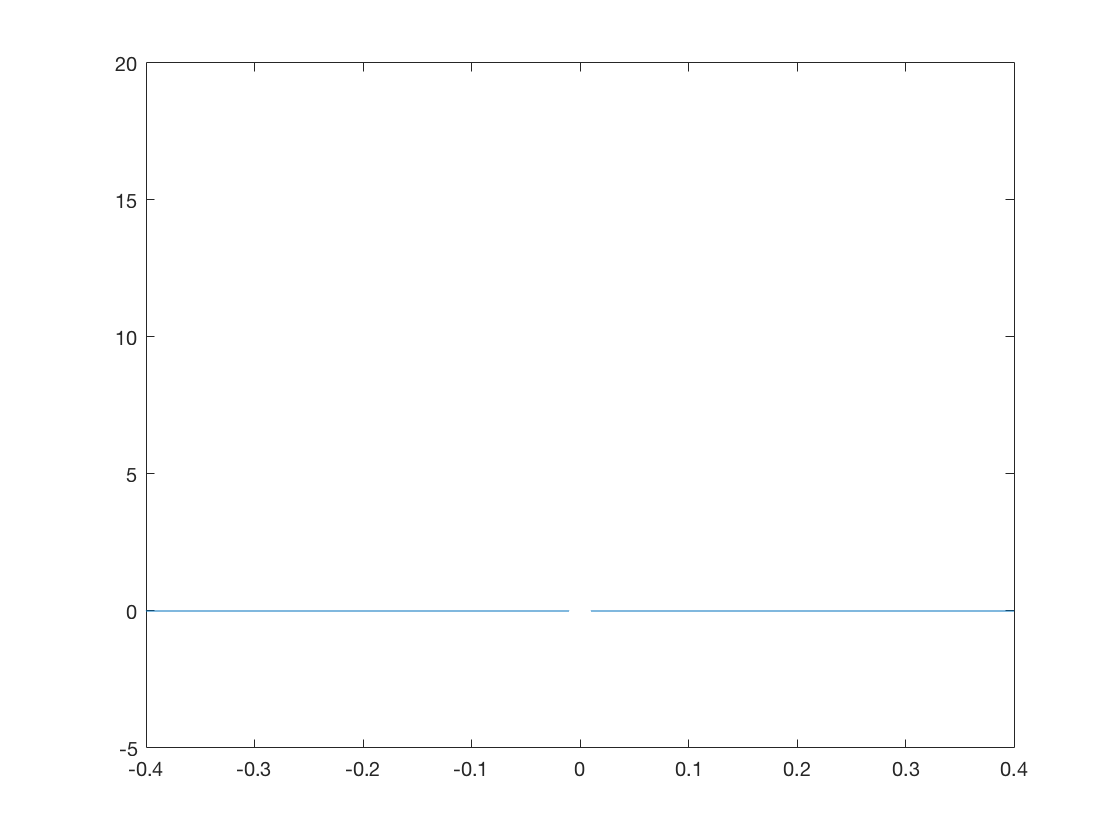

DT=dirac(T);
plot(T,delta)
axis([-range/25 range/25 -range/2 20])

int(dirac(t),t,-Inf,Inf)

$$ans = 1$$

dirac(0)

ans = Inf

dirac(27826)

ans = 0

f=@(t)4-t^3

f = function_handle with value:
    @(t)4-t^3


f0=f(0)

f0 = 4

t0=1

t0 = 1

f0=int(f(t)*dirac(t),t,-Inf,Inf)

$$f0 = 4$$

f1=int(f(t)*dirac(t-t0),t,-Inf,Inf)

$$f1 = 3$$

int(f(tau)*dirac(t-tau),tau,-Inf,Inf)

$$ans = 4-t^{3}$$

int(dirac(tau)*f(t-tau),tau,-Inf,Inf)

$$ans = 4-t^{3}$$

Impulsdarstellung zeitkontinuierlicher Signale